## Load the Data

clear;
folder = 'Exp3/';
files = dir('Exp3/*.mat');
lenfile = length(files);
voltage_freq = zeros(1,lenfile);
table_gain = zeros(1,lenfile);
motor_gain = zeros(1,lenfile);
table_phase_angle = zeros(1,lenfile);
motor_phase_angle = zeros(1,lenfile);


for k = 1 : lenfile
    baseFileName = files(k).name;
    fullFileName = fullfile(folder, baseFileName);
    fprintf(1, 'Now reading %s \n', fullFileName);
    load(fullFileName)
    time = eval(strcat(baseFileName(1:7),'X.Data'));
    pos_motor = eval(strcat(baseFileName(1:7),'Y(1).Data'));
    %pulse_gen_out = eval(strcat(baseFileName(1:7),'Y(2).Data'));
    pos_table = eval(strcat(baseFileName(1:7),'Y(3).Data'));
    voltage = eval(strcat(baseFileName(1:7),'Y(4).Data'));
    
    [freq_voltage, gain_table, phase_angle_table, gain_motor, phase_angle_motor] = get_bode(pos_motor, pos_table, voltage);
    
    voltage_freq(k) = freq_voltage;
    table_gain(k) = gain_table;
    motor_gain(k) = gain_motor;
    table_phase_angle(k) = phase_angle_table;
    motor_phase_angle(k) = phase_angle_motor;
end

Now reading Exp3\exp001.mat 
Now reading Exp3\exp002.mat 
Now reading Exp3\exp003.mat 
Now reading Exp3\exp004.mat 
Now reading Exp3\exp005.mat 
Now reading Exp3\exp006.mat 
Now reading Exp3\exp007.mat 
Now reading Exp3\exp008.mat 
Now reading Exp3\exp009.mat 
Now reading Exp3\exp010.mat 
Now reading Exp3\exp011.mat 
Now reading Exp3\exp012.mat 
Now reading Exp3\exp013.mat 
Now reading Exp3\exp014.mat 
Now reading Exp3\exp015.mat 
Now reading Exp3\exp016.mat 
Now reading Exp3\exp017.mat 
Now reading Exp3\exp018.mat 
Now reading Exp3\exp019.mat 
Now reading Exp3\exp020.mat 
Now reading Exp3\exp021.mat 
Now reading Exp3\exp022.mat 
Now reading Exp3\exp023.mat 
Now reading Exp3\exp024.mat 
Now reading Exp3\exp025.mat 
Now reading Exp3\exp026.mat 
Now reading Exp3\exp027.mat 
Now reading Exp3\exp028.mat 
Now reading Exp3\exp029.mat 
Now reading Exp3\exp030.mat 
Now reading Exp3\exp031.mat 
Now reading Exp3\exp032.mat 
Now reading Exp3\exp033.mat 
Now reading Exp3\exp034.mat 
Now reading Ex

## Plot for visualization

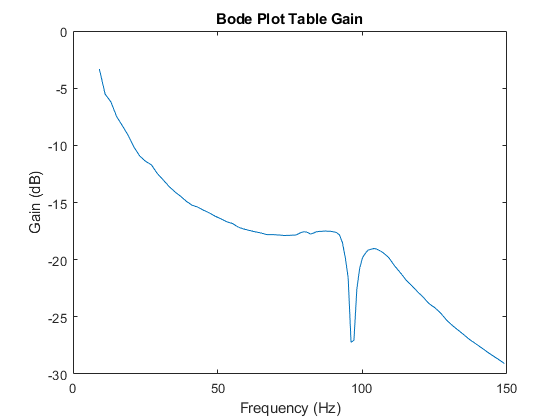

plot(voltage_freq, table_gain)
title('Bode Plot Table Gain')
ylabel('Gain (dB)')
xlabel('Frequency (Hz)')

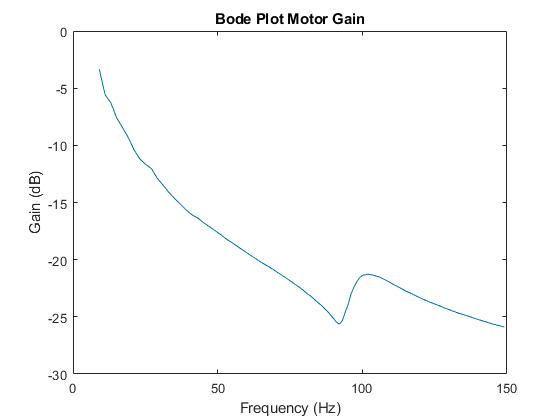


plot(voltage_freq, motor_gain)
title('Bode Plot Motor Gain')
ylabel('Gain (dB)')
xlabel('Frequency (Hz)')

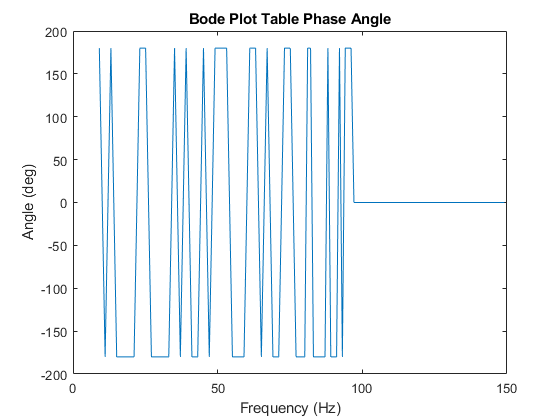


plot(voltage_freq, table_phase_angle)
title('Bode Plot Table Phase Angle')
ylabel('Angle (deg)')
xlabel('Frequency (Hz)')

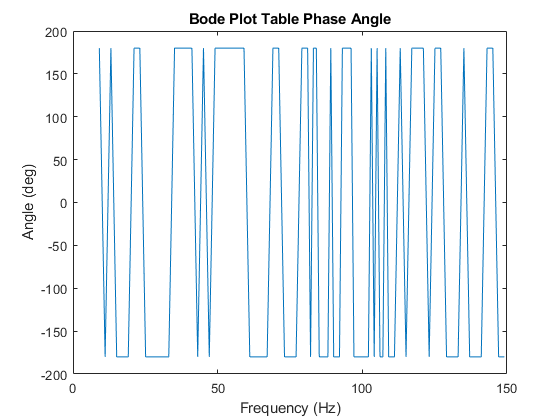


plot(voltage_freq, motor_phase_angle)
title('Bode Plot Table Phase Angle')
ylabel('Angle (deg)')
xlabel('Frequency (Hz)')